## Project 1: Matched Filters: Applications of Cross-Correlation

John Smith - 800776897

Fall 2022

clear all
clc

## Task 1

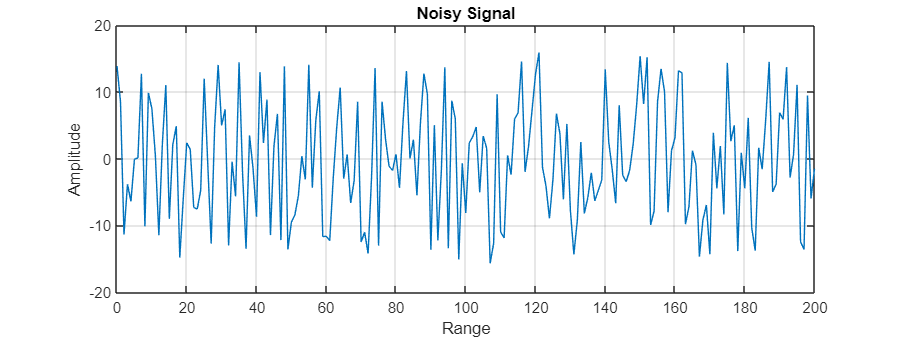

% Range
n = 0:200;

% Phase of the signal
phase = 0;

% N distribution for ourr random number; ie how many random numbers 
N = length(n);

% Uniform sinusoidal
x = cos((pi/15).*n + phase);

% Amplitude of +/-15, so 30*random number with distribution of -0.5 to 0.5
e = 30*(rand(1,N)-0.5);        
figure('Position', [0 0 800 300])
y = x + e;
figure(1), plot(n,y)
title('Noisy Signal')
xlabel('Range')
ylabel('Amplitude')
grid("on")

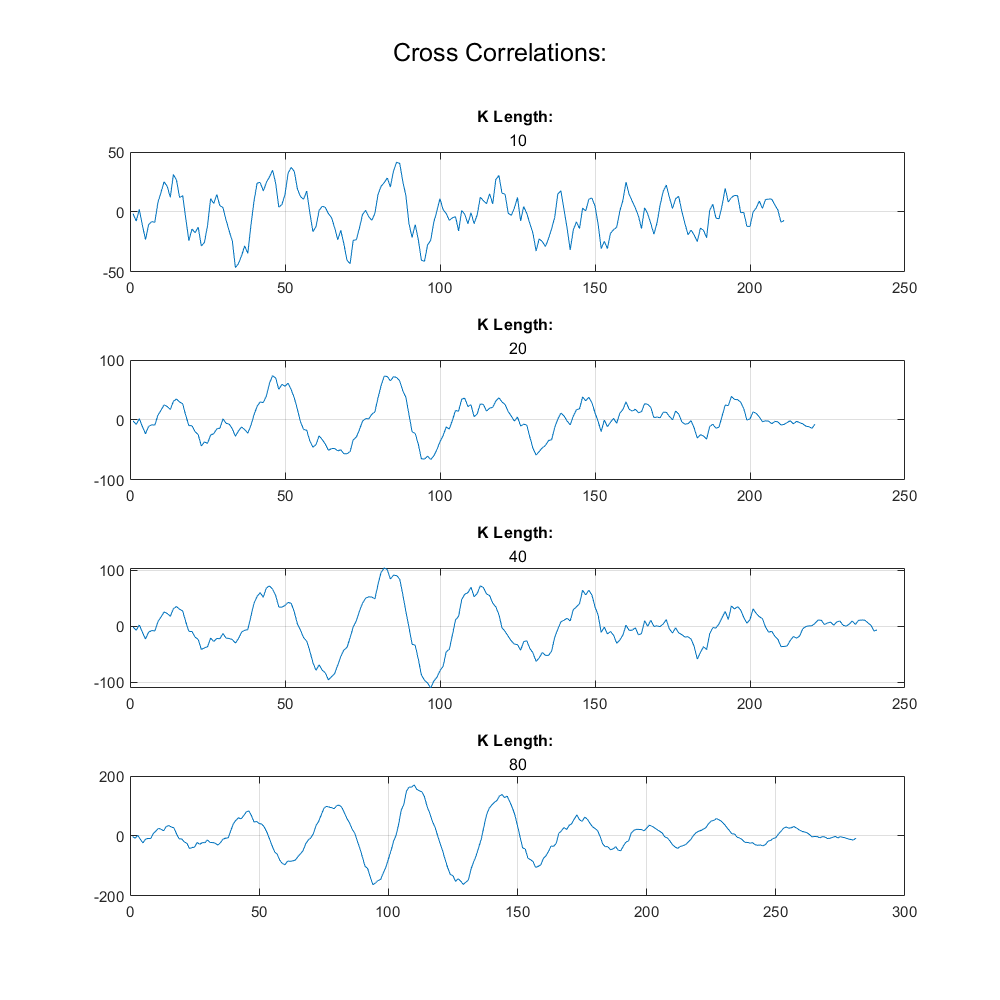

k_lengths_list = [10 20 40 80];

figure('Position', [0 0 800 800])
for i = 1:length(k_lengths_list)
    sgtitle('Cross Correlations:')
    m = 0:k_lengths_list(i);
    h_n = cos((pi/15).*m + phase);
    rxh = conv(fliplr(y), h_n);
    subplot(4,1,i);
    figure(2),plot(rxh)
    title("K Length: ", k_lengths_list(i))
    [~, locs] = findpeaks(rxh);
    mean_diff(i) = mean(diff(locs));
    grid("on")
end

mean_diff

mean_diff =     4.4130    4.6087    5.4186    8.2424


Array indices must be positive integers or logical values.

peak_diff=((65-28)+(93-65)+(123-93)+(152-123)+(183-152)+(203-183)+(233-203)+(262-233))/8

**3. (5pts) Use the location of peaks in the output to estimate the period of the noisy sinusoidal input x[n]. State the estimated value of the sinusoid period.**

To find the period, the lag value at each peak was found. The difference between each consecutive peak was found and averaged using the following equation: 


$$T=\frac{\left(x_1 -x_2 \right)+\left(x_2 -x_3 \right)+\ldotp \ldotp \ldotp +\left(x_{n-1} -x_n \right)}{n-1}$$
       

Using this equation, the equation peak_diff was created based on the K = 80 peak values. This produced an esitmated period of** 29.25**

**4. (5pts) Provide a 1-paragraph explanation of how the variable K impacts the estimation of the period.**

From the output displayed above, we can observe that the higher the K-value, the smoother and more sinusoidal the signal gets. As the K-value increases, the number of iterations and ultimately datapoints increases. Therefore the higher the K-value, the more accurate the filter and begins to smooth out the signal.

**5. (5pts) If the noise amplitude were increased, how would you change h[n] to get a better estimate?**

If the noise amplitude were increased, h[n] may need to be changed to to contain a larger amplitude. This would allow the signal to pass more noise.  

**6. (5pts) Is it also possible to estimate the phase of the function if **$\phi \not= 0$**? If so, give an idea of how youwould do this? Hint : From the program above, let **$\phi =\pi$** or **$\phi =\frac{\pi }{2}$ **and observe how the value of the indices of your peaks change.**

By changing the phase of the non-shifted signal to a phase of $\frac{\pi }{2}$ and $\pi$it can be observed that the cross-correlation is shifted by a constant; roughly the period. From this observation we can conclud that by measuring the signal with a phase of zero and compare that to one with unknown phase, the unknown phase can be calculated using the difference from peak-to-peak of the two signals.  

## Task 2

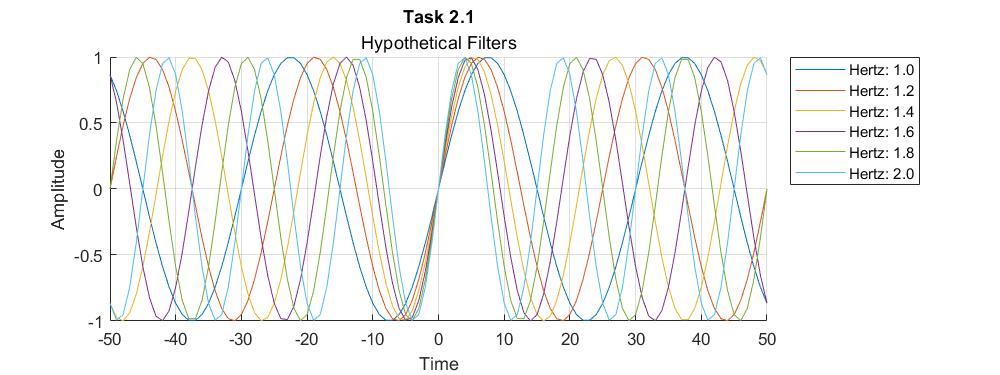

T = 1/30;
n = -50:50;
phase = 0;
pixelval = importdata("red_pixel_values.mat");
figure('Position', [0 0 800 300])
hold on
for i = 0:5
    hertz = i * 0.2 +1;
    h_n = sin(pi*2*hertz*T*n);
    figure(3),plot(n,h_n)
    title("Task 2.1")
    subtitle("Hypothetical Filters")
end
legend('Hertz: 1.0','Hertz: 1.2','Hertz: 1.4','Hertz: 1.6','Hertz: 1.8','Hertz: 2.0')
legend('Location','northeastoutside')
xlabel('Time')
ylabel('Amplitude')
grid("on")
hold off;

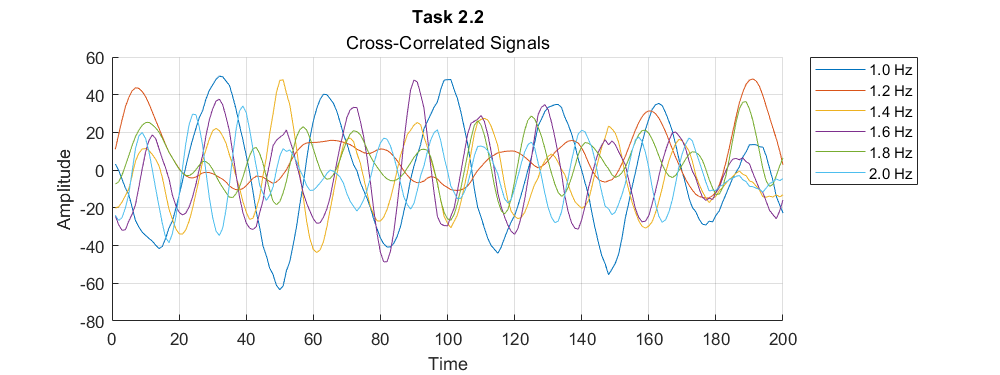

figure('Position', [0 0 800 300])
hold on
for i = 0:5
    hertz = i * 0.2 +1;
    h_n = sin(pi*2*hertz*T*n);
    y_n_1 = conv(fliplr(pixelval), h_n, "valid");
    figure(4), plot(y_n_1)
end
hold off
title("Task 2.2")
subtitle("Cross-Correlated Signals")
legend('1.0 Hz','1.2 Hz','1.4 Hz','1.6 Hz','1.8 Hz','2.0 Hz')
legend('Location','northeastoutside')
xlabel('Time')
ylabel('Amplitude')
grid("on")
hold off

for i = 0:5
    hertz = i * 0.2 +1;
    h_n = sin(pi*2*hertz*T*n);
    y_n_1 = conv(fliplr(pixelval), h_n, "valid");
    max(y_n_1)
end

ans = 49.8560

ans = 48.4132

ans = 47.9501

ans = 47.8345

ans = 36.3109

ans = 34.0398

for i = 0.82:0.001:0.84
    h = sin(pi*2*i*n.*(T));
    max(h);
    i;
end

From the max(h) and i calculations, we can observe that that the signal stays high at 0.8280Hz to 0.8386Hz. Taking the midpoint, we can conclude and use 0.8386Hz. When using the 0.8386Hz value, the max and min value flucuate widley, having a crest(max) and trough(min) occur on different wave cycles as seen below. 

**3. (10pts) Indicate which filter has a frequency closest to the unknown frequency present in the data file.**

**Clearly state the frequency indicated as your "best" guess from the outputs of (2).**

As we can see, the max value occurs at 1Hz. To get the true max, 0.8Hz to 1Hz was calculated.

**4. (10pts) Refine your "best" guess answer for the unknown frequency by changing your MATLAB code. **

**Indicate your improved guess (different than that from (3)). Explain how you arrived at your improved solution.**

Because the max occured at 1Hz, lower frequencies from 0.8Hz to 1.0Hz were explored. Refining even further, the precision of the FOR loop was increased and the frequency that fit best lied between 0.9157Hz to 0.9165Hz. To obtain a singular frequency, these two start and end frequencies were averaged to obtain a best fit frequency of 0.9161Hz.

## Task 3

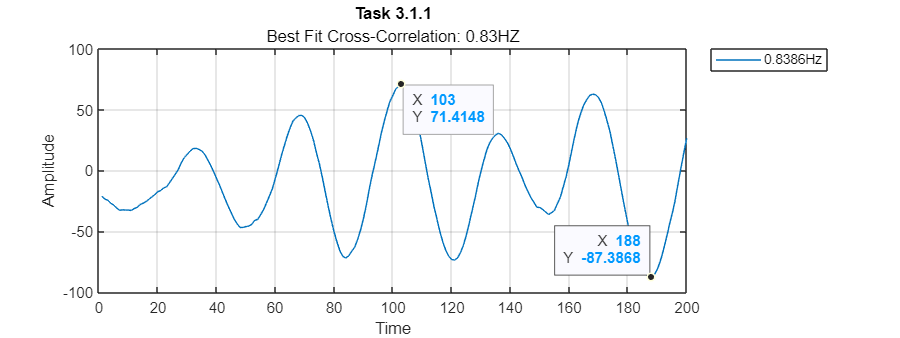

% Using 0.8386Hz

figure('Position', [0 0 800 300])
h_best_hertz = 0.8386;
h_best = sin(pi*2*h_best_hertz*n.*(T));
y_n_2 = conv(pixelval, fliplr(h_best), "valid");
figure(5),plot(y_n_2)
title("Task 3.1.1")
subtitle("Best Fit Cross-Correlation: 0.83HZ")
legend('0.8386Hz')
legend('Location','northeastoutside')
xlabel('Time')
ylabel('Amplitude')
grid("on")
ax = gca;
chart = ax.Children(1);
datatip(chart,103,71.4148);
datatip(chart,188, -87.3868);

[x,y] = max(y_n_2)

x = 71.4148

y = 103

[x,y] = min(y_n_2)

x = -87.3868

y = 188

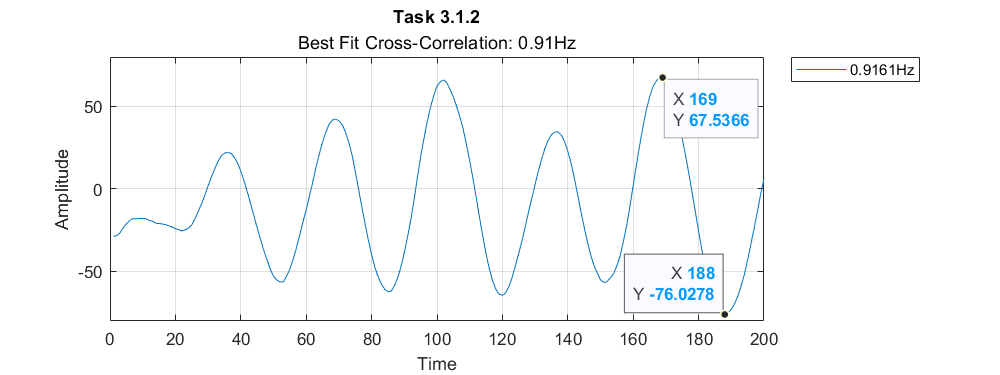

% Using 0.9161Hz
figure('Position', [0 0 800 300])
h_best_hertz = 0.9161;
h_best = sin(pi*2*h_best_hertz*n.*(T));
y_n_2 = conv(pixelval, fliplr(h_best), "valid");
figure(6),plot(y_n_2)
title("Task 3.1.2")
subtitle("Best Fit Cross-Correlation: 0.91Hz")
legend('0.9161Hz')
legend('Location','northeastoutside')
xlabel('Time')
ylabel('Amplitude')
grid("on")
ax = gca;
chart = ax.Children(1);
datatip(chart,169,67.5366);
datatip(chart,188, -76.0278);

The maximum and minum should occur on the same wave cycle, so the process was repeated from 0.91Hz and 0.93Hz at 0.001Hz increments. The signal stayed high between 0.9157 and 0.9165. The median of these two frequencies was calculted and, therefore, I chose 0.9161Hz as my line of best fit. 

sum(h)

ans = -4.4409e-16

From this we can conclue that the sum of the filter coefficients is $-4\ldotp 4409{\mathrm{x10}}^{-16}$ which is essentially zero; **Task 2.2**. 

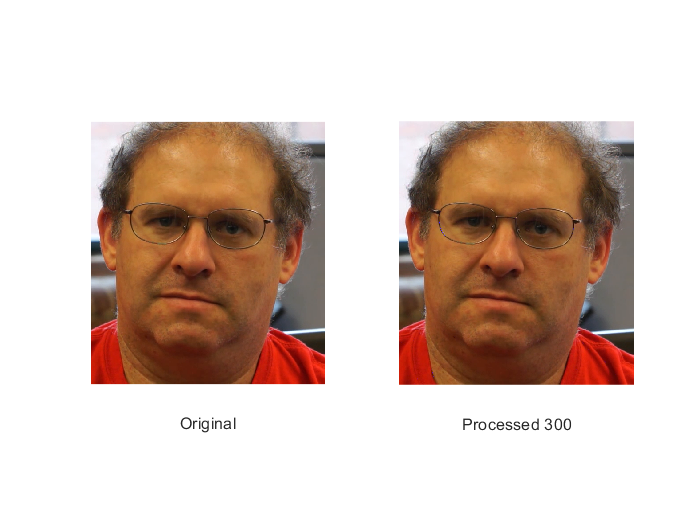

video = load('rgb_video_values.mat');

% downsample the video images for debugging and testing by a factor of (downsample_by_M)
% IMPORTANT: Set downsample_by_M = 1 for your final project results.
downsample_by_M = 1;
if (downsample_by_M > 1) 
    rgb_images = reshape(video.imageStack_uint8,[video.rows,video.cols,3,video.num_frames]);
    rgb_small = rgb_images(1:downsample_by_M:video.rows,1:downsample_by_M:video.cols,:);
    video.cols = floor((video.cols+1)/downsample_by_M);
    video.rows = floor((video.rows+1)/downsample_by_M);
    video.imageStack_uint8 = reshape(rgb_small,[video.rows*video.cols*3,video.num_frames]);
end

x_of_n = video.imageStack_uint8;

% REPLACE CODE HERE TO SET THE VALUE OF y_of_n and set your own alpha value
n = -50:50;
h_best_hertz = 0.9161;
h_best = sin(pi*2*h_best_hertz*n.*(T));
alpha = 2;
y_of_n = conv2(x_of_n,fliplr(h_best),"same");

rgb_images = reshape(x_of_n,[video.rows,video.cols,3,video.num_frames]);
rgb_processed = reshape(y_of_n,[video.rows,video.cols,3,video.num_frames]);
new_rgb_images = rgb_images + uint8(alpha*rgb_processed);
for frame=1:video.num_frames
    figure(7),subplot(1,2,1),imshow(rgb_images(:,:,:,frame),'InitialMagnification','fit'), xlabel('Original');
    framestr=sprintf('Processed %d',frame);
    figure(7),subplot(1,2,2),imshow(new_rgb_images(:,:,:,frame),'InitialMagnification','fit'),xlabel(framestr);
    pause(1/30);
end

minframe = 188;
maxframe = 169;

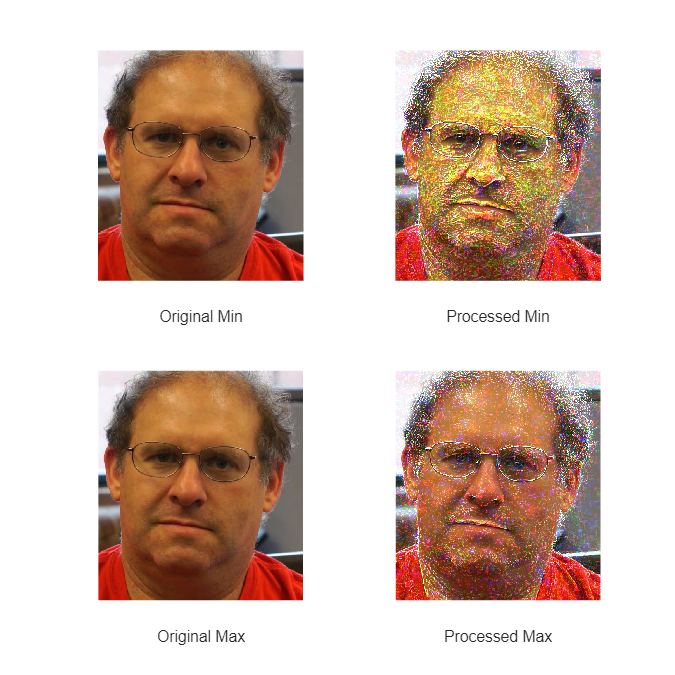

figure('Position', [0 0 600 600])
figure(8),subplot(2,2,1),imshow(rgb_images(:,:,:,minframe)),xlabel('Original Min');
figure(8),subplot(2,2,2),imshow(new_rgb_images(:,:,:,minframe)),xlabel('Processed Min');
figure(8),subplot(2,2,3),imshow(rgb_images(:,:,:,maxframe)),xlabel('Original Max');
figure(8),subplot(2,2,4),imshow(new_rgb_images(:,:,:,maxframe)),xlabel('Processed Max');

The red pixel values from the video are magnified in the image ,allowing for a visualization of the heart beating. The amplification of the red pixel values occurs due to the the green and blue color values being uncorrelated with those of the red pixels. To make this correlation visible, the filtered signal is added back to the original video. By doing this, a visible shift in the red spectrum can be seen. 

To calculate the heartbeat, we must first count the "beats" of the video. The BPM can easily be calculated by multiplying the frequency by a factor of 60. The equation to do this is: 


$$\mathrm{BPM}=f*60\frac{s}{\min }$$


Using this equation we can calculate the heartbeat of the subject in the video. Taking the chosen filter frequency of 0.9161Hz, we obtain the subjects heartbeat to be** 54.97 BPM**. 